syms i V R L t f C;
%f = 1/2*pi*sqrt(L*C);
%i=Q/CR
i  =(V/R)* (1 - exp(-R*t/L));
didt = diff(i,t);
subs(i,t,0)

$$ans = 0$$

I=dsolve('Di + R/L*i + 1/(L*C)','i(0)=0');

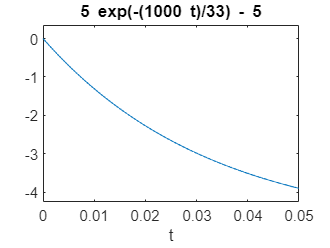

iC=subs(I,{R,L,C,V},{100.0,3.3,0.002,0.033});
ezplot(iC,[0,0.05]);

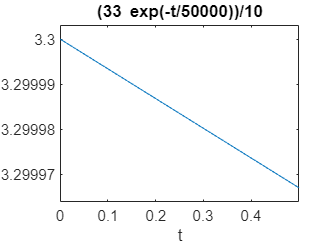

vC=V*exp(-t/R*C);
vC_out=subs(vC,{V,R,C},{3.3,100.0,0.002});
ezplot(vC_out,[0,0.5])